“I certify that this represents my own work and that I have not worked with classmates or other individuals to complete this assignment.” 

Benjamin Werb

*Note* Disregard U

1. Make a preliminary assessment of the data. First, plot time series of the total wind speed (“WSPD”), zonal wind (“UWND”), and meridional wind (“VWND”). What is the time interval between data points? What is the time gap between the data files? How are gaps in the data handled? Since there are some gaps in the data, for the rest of this problem set, you will need to fill the gaps. Fill the gaps in each record by linear interpolation. (You can do this with the Matlab function interp1 or xarray.interpolate na in python.) Do not try to interpolate across the gaps between the 3 records, since the gaps are several hours long. 

The time interval between data points is 10 minutes. Data1-Data2 is a 9 hour, 30 minute  gap. Data2-Data3 is 2 hour, 10 minute gap. Gaps in the data are filled in with NaNs.

- Fill NaNs with linear interp

addpath('/Users/benjaminwerb/Documents/GitHub/SIO221a_Github_code/HW5_data/');

%explore data format
ncdisp('OS_T8S110W_DM134A-20150425_D_WIND_10min.nc')

Source:
           /Users/benjaminwerb/Documents/GitHub/SIO221a_Github_code/HW5_data/OS_T8S110W_DM134A-20150425_D_WIND_10min.nc
Format:
           classic
Global Attributes:
           time_coverage_start          = '2015-04-26T01:00:00Z'
           time_coverage_end            = '2016-03-21T15:00:00Z'
           featureType                  = 'timeSeries'
           format_version               = '1.3'
           platform_code                = 'T8S110W'
           platform_type                = 'TAO Refresh'
           site_code                    = 'T8S110W'
           network                      = 'TAO'
           wmo_platform_code            = '32319'
           update_interval              = 'void'
           title                        = 'TAO Delayed/Mixed Mode Data'
           summary                      = 'Delayed/Mixed mode data from NDBC Tropical Atmosphere Ocean (TAO) Array'
           source                       = 'moored surface buoy'
           keywords               

ncdisp('OS_T8S110W_DM183A-20160321_D_WIND_10min.nc')

Source:
           /Users/benjaminwerb/Documents/GitHub/SIO221a_Github_code/HW5_data/OS_T8S110W_DM183A-20160321_D_WIND_10min.nc
Format:
           classic
Global Attributes:
           time_coverage_start          = '2016-03-22T00:30:00Z'
           time_coverage_end            = '2017-06-05T21:00:00Z'
           featureType                  = 'timeSeries'
           format_version               = '1.3'
           platform_code                = 'T8S110W'
           platform_type                = 'TAO Refresh'
           site_code                    = 'T8S110W'
           network                      = 'TAO'
           wmo_platform_code            = '32319'
           update_interval              = 'void'
           title                        = 'TAO Delayed/Mixed Mode Data'
           summary                      = 'Delayed/Mixed mode data from NDBC Tropical Atmosphere Ocean (TAO) Array'
           source                       = 'moored surface buoy'
           keywords               

ncdisp('OS_T8S110W_DM231A-20170606_D_WIND_10min.nc')

Source:
           /Users/benjaminwerb/Documents/GitHub/SIO221a_Github_code/HW5_data/OS_T8S110W_DM231A-20170606_D_WIND_10min.nc
Format:
           classic
Global Attributes:
           time_coverage_start          = '2017-06-06T19:10:00Z'
           time_coverage_end            = '2018-04-27T16:00:00Z'
           featureType                  = 'timeSeries'
           format_version               = '1.3'
           platform_code                = 'T8S110W'
           platform_type                = 'TAO Refresh'
           site_code                    = 'T8S110W'
           network                      = 'TAO'
           wmo_platform_code            = '32319'
           update_interval              = 'void'
           title                        = 'TAO Delayed/Mixed Mode Data'
           summary                      = 'Delayed/Mixed mode data from NDBC Tropical Atmosphere Ocean (TAO) Array'
           source                       = 'moored surface buoy'
           keywords               

%make struct
df = Structify('OS_T8S110W_DM134A-20150425_D_WIND_10min.nc' ...
    ,'OS_T8S110W_DM183A-20160321_D_WIND_10min.nc', ...
    'OS_T8S110W_DM231A-20170606_D_WIND_10min.nc');

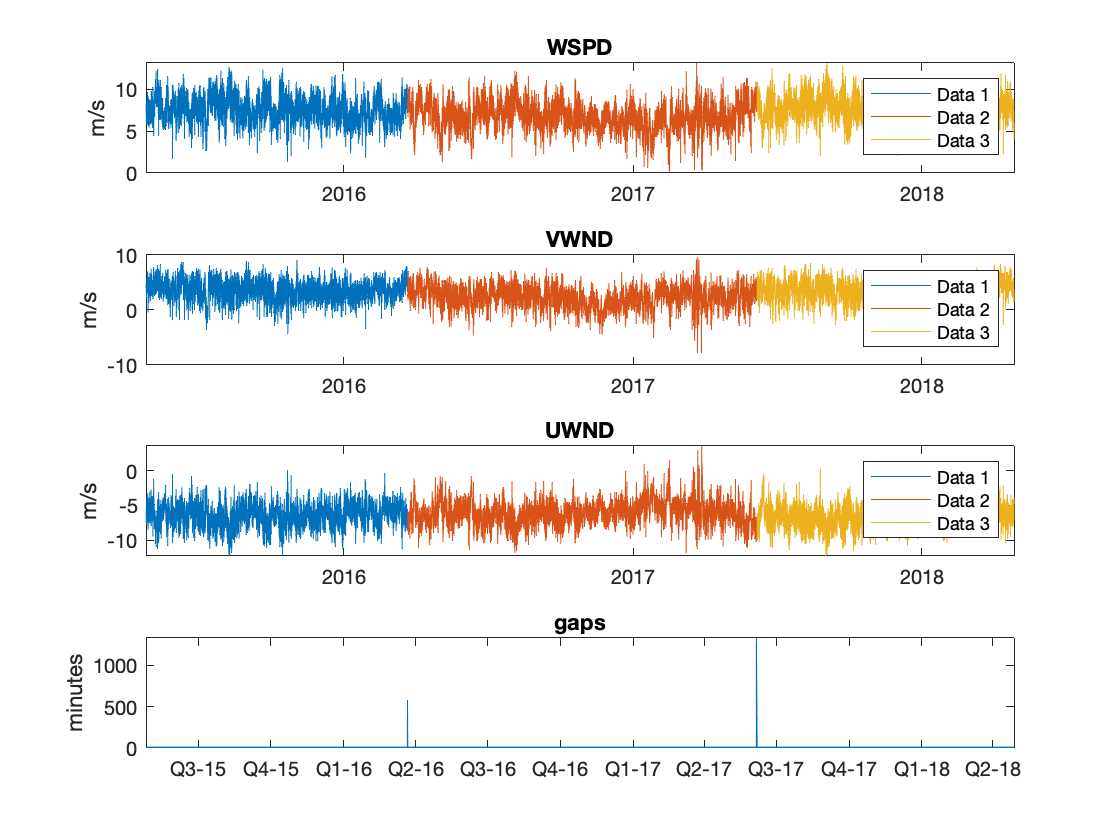

%Explore time series
figure(1)
clf
tiledlayout(4,1)
nexttile;
plot(df.t1_dnum,df.WSPD1)
hold on
plot(df.t2_dnum,df.WSPD2)
plot(df.t3_dnum,df.WSPD3)
xlim([df.t_dnum(1) df.t_dnum(end)])
datetick('x',10,'keeplimits')
title([char(df.names(1))])
ylabel([char(df.units(1))])
legend('Data 1', 'Data 2', 'Data 3')

nexttile
plot(df.t1_dnum,df.VWND1)
hold on
plot(df.t2_dnum,df.VWND2)
plot(df.t3_dnum,df.VWND3)
xlim([df.t_dnum(1) df.t_dnum(end)])
datetick('x',10,'keeplimits')
title([char(df.names(2))])
ylabel([char(df.units(2))])
legend('Data 1', 'Data 2', 'Data 3')

nexttile
plot(df.t1_dnum,df.UWND1)
hold on
plot(df.t2_dnum,df.UWND2)
plot(df.t3_dnum,df.UWND3)
xlim([df.t_dnum(1) df.t_dnum(end)])
datetick('x',10,'keeplimits')
title([char(df.names(3))])
ylabel([char(df.units(3))])
legend('Data 1', 'Data 2', 'Data 3')


%Find Gaps/NaNs/Fillers
x = diff(df.t1);
x = diff(df.t2);
x = diff(df.t3);
datevec(df.t_dnum);
idx1 = 1:1:length(df.t1);
idx2 = idx1(end)+1:1:idx1(end)+length(df.t2);
idx3 = idx2(end)+1:1:idx2(end)+length(df.t3);

end1 = datevec(df.t_dnum(idx1(end)));
start2 = datevec(df.t_dnum(idx2(1)));

end2 = datevec(df.t_dnum(idx2(end)));
start3 = datevec(df.t_dnum(idx3(1)));

nexttile
x = diff(df.t_dnum) * 1440;
plot(df.t_dnum(1:end-1),x)
datetick
ylabel('minutes')
title('gaps')
xlim([df.t_dnum(1) df.t_dnum(end)])

df = FillGaps(df); %Fill gaps with lin interp

2. Segment the data into 60-day segments with 50% overlap. How many segments do you have for each of the data files? How many points are in each segment? Determine the frequencies (in cycles per day) that you will be able to analyze when you Fourier transform the data. 

Data 1:

- 10 segments each containing 8640 points

Data 2:

- 13 segments each containing 8640 points

Data 3:

- 9 segments each containing 8640

The original Data has approximately between 1/330-1/360 cycles per day resolution and when segmented has 1/60 cycles per day resolution.

Chunks = Chunkify(df); 

test2 =     8.6200    8.1000    8.8000    9.6600    9.3800    9.7500    9.3900    9.3000    9.3000    8.9900    9.1000   10.1200    9.4300    8.7100    9.4900    9.4000    9.4900    9.5900    9.9100    9.0400    9.4000    9.2800    9.1200    9.0300    8.6800    8.8300    8.1900    8.4300    8.9800    8.6300    9.3000    8.6300    8.6800    8.2300    7.8400    7.9600    7.6200    8.0200    8.8900    7.7600    7.5500    7.5100    7.7300    8.0800    7.6800    6.6700    7.1800    6.7500    7.0100    7.8400


%Segment data into 60 day chunks using reshape
%Note that some data is not used to ensure each 
% segment is exactly 60 days.

3.Compute and plot spectra using 3 different approaches, for the 2015 wind speed record only. Compute the spectrum from the raw data, from the detrended data, and from the detrended data with a Hanning window applied. How does detrending and windowing alter the spectrum in this case?

- Detrending and Windowing the spectrum prevent enery leakage and make it very clear that there are energy spikes at 1, 2, 1.3,  2.3, .4 cycles per day. Removing the mean and detrending shifts a huge amount of the energy out of the center (0 cycles per day).

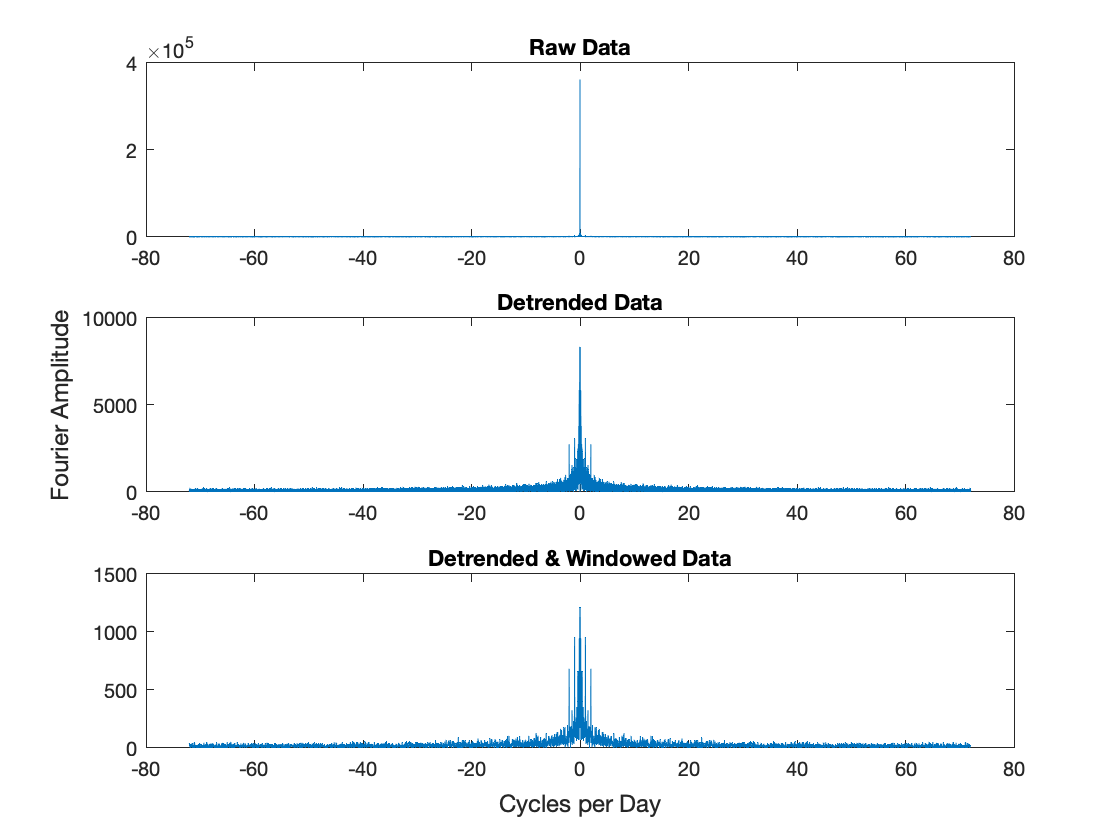

figure(2)
clf
m = tiledlayout(3,1);
ylabel(m, 'Fourier Amplitude')
xlabel(m, 'Cycles per Day')
nexttile
f_vector = frqvector(df.WSPD1,10);
y = Spectra(df.WSPD1,0,0,0);
plot(f_vector,y)
title('Raw Data')
nexttile
f_vector = frqvector(df.WSPD1,10);
y = Spectra(df.WSPD1,1,0,0); %detrended
plot(f_vector,y)
title('Detrended Data')
nexttile
f_vector = frqvector(Chunks.WSPD1,10);
y = Spectra(Chunks.WSPD1,1,1,1); %detrended, hanning, chunked
plot(f_vector,y)
title('Detrended & Windowed Data')

4. Add uncertainty estimates to the 2015 wind speed spectra. Indicate whether you think the uncertainty should differ for the 3 cases. 

- The uncertainty should decrease when averaging over multiple time series. When segmenting the data you increase your level of certainty, however, your frequency resolution decreases.

- Uncertainty should be lowest for the hanning window detrended data, followed by just detrended and then raw.

figure(3)
clf
f_vector = frqvector(Chunks.WSPD1,10);
y = Spectra(Chunks.WSPD1,1,1,1);
loglog(f_vector,y,'LineWidth',1)
hold on
[x, errorbar] = ErrorBar(1.00,f_vector,y);
loglog(x,errorbar,'LineWidth',3,'LineStyle','--')% this is how I can get a line
legend('2015 Spectra','Uncertainty Estimate')
title('2015 Spectra')

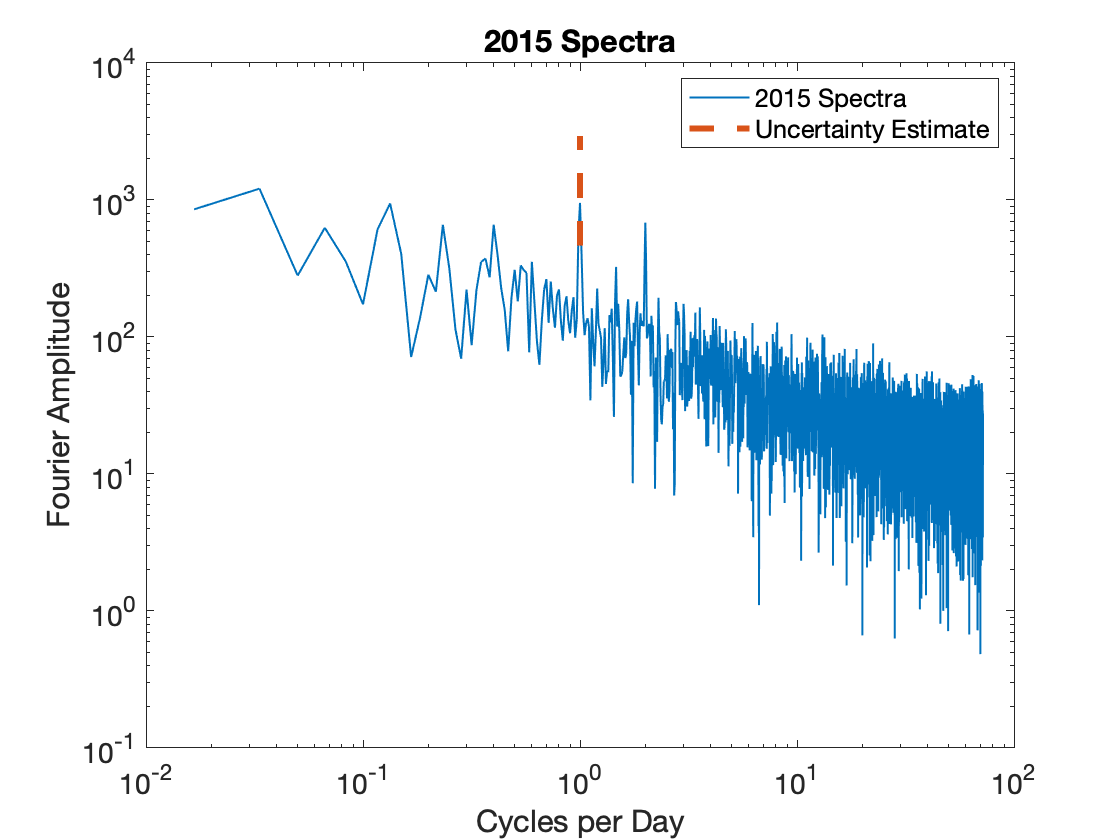

xlabel('Cycles per Day')
ylabel('Fourier Amplitude')

5. Compute the wind speed spectrum using data from all three data files. Do this just using the detrended and Hanning-windowed records. Be sure to compute the uncertainty estimate. Overlay the multi-year spectrum over the 2015 spectrum you computed earlier. How do they differ? Why? Can the differences be explained by differences in the uncertainties? 

- The multi-year spectrum has less variance in fourier amplitude at higher frequencies. Peaks appear to be at very similar frequencies so the differences can be explained by the uncertainties. At lower frequencies the spectra are different because the multi year spectra can resolve lower frequency data.

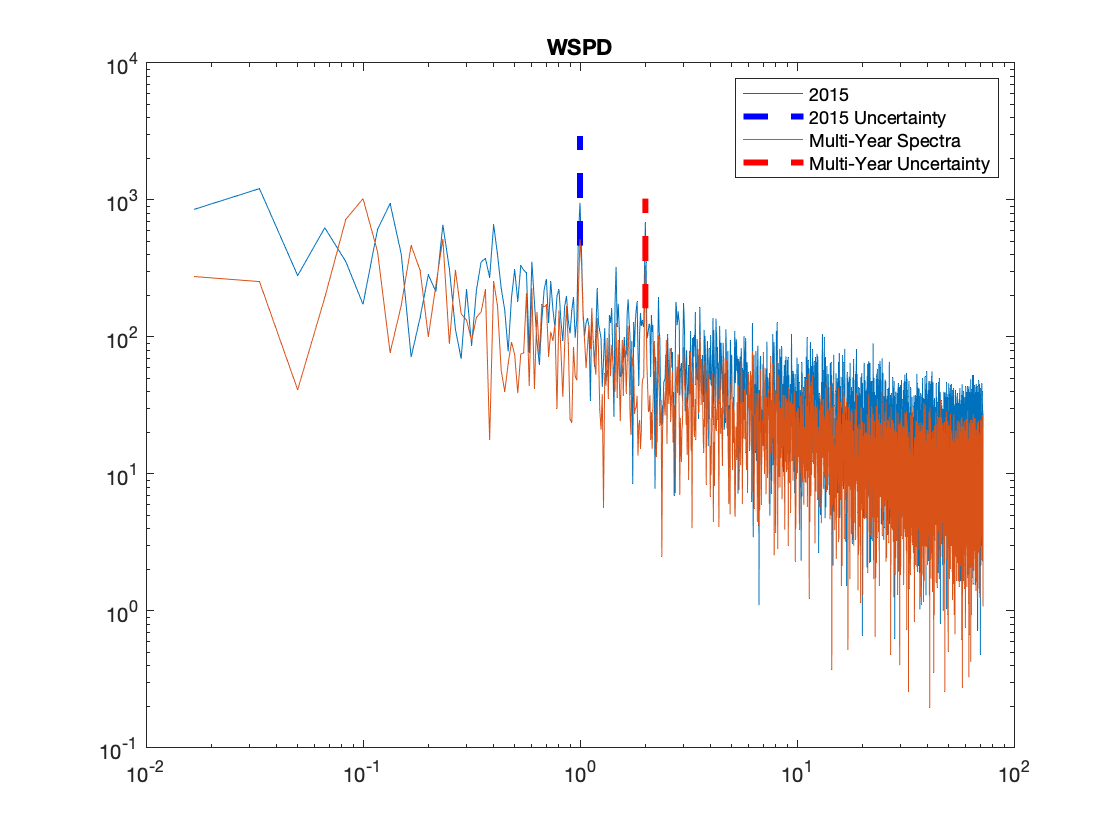

figure(4)
clf
tiledlayout(1,1)
nexttile
f_vector = frqvector(Chunks.WSPD1,10);
y = Spectra(Chunks.WSPD1,1,1,1);
loglog(f_vector,y,'LineWidth',.5,'color','#0072BD')
hold on

[x, errorbar] = ErrorBar(1.00,f_vector,y);
loglog(x,errorbar,'LineWidth',3,'LineStyle','--','color','blue')

f_vector = frqvector(Chunks.WSPD,10);
y = Spectra(Chunks.WSPD,1,1,1);
loglog(f_vector,y,'LineWidth',.5,'color','#D95319')

[x, errorbar] = ErrorBar(2.00,f_vector,y);
loglog(x,errorbar,'LineWidth',3,'LineStyle','--','color','red')
legend('2015','2015 Uncertainty', 'Multi-Year Spectra', 'Multi-Year Uncertainty')
title('WSPD')

6. Compare the spectra for wind speed, zonal wind, and meridional wind. Use all 3 data files, and be sure to detrend and Hanning window. **Examine the peaks at the diurnal and semi-diurnal frequencies. How do they differ? Are the differences statistically significant? What do you hypothesize might account for differences?**

- The three spectra have a peak at both 1 and 2 cycles per day (diurnal and semidiurnal spectra).

- The amplitudes differ. WSPD: (1, 549) (2, 331). VWND: (1, 1493) (2, 405). UWND: (1, 531) (2, 400).

- This makes me believe that these measurements are related to each other and possibly controlled by VWND because it has the highest amplitude.

- The differences all appear to be within error bars of each other so are not statistically significant.

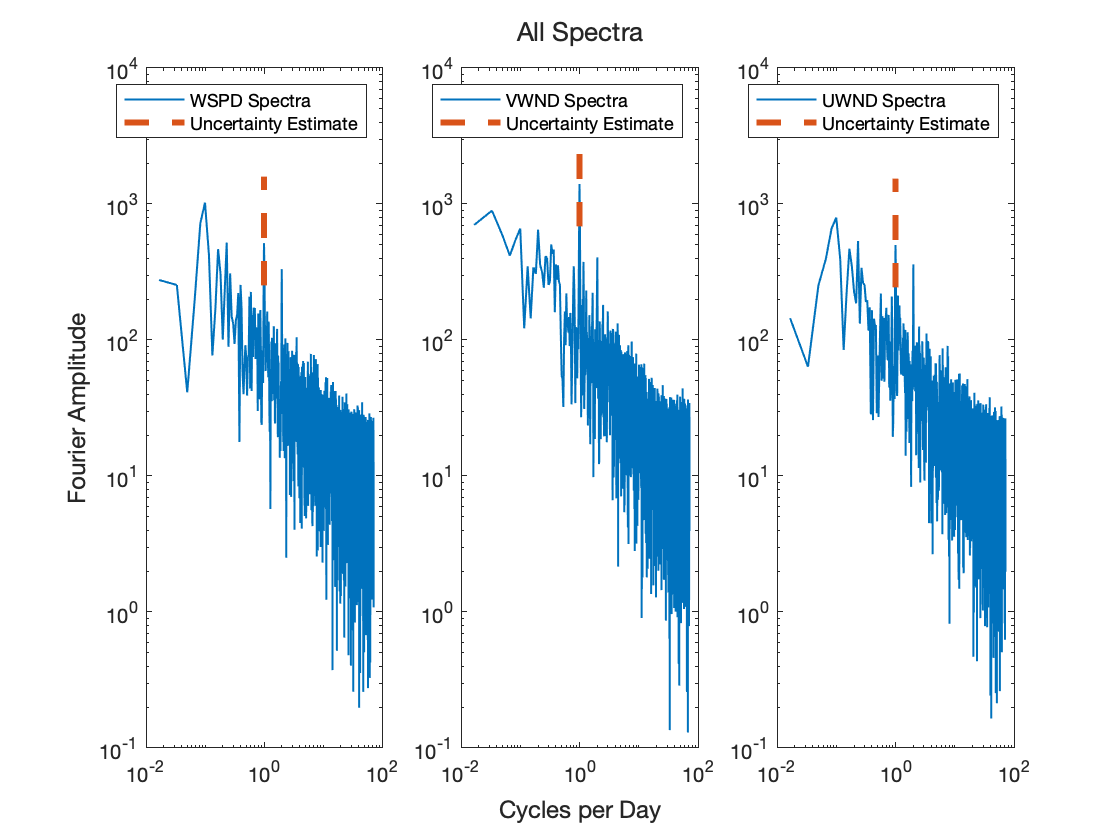

figure(5)
clf
m = tiledlayout(1,3);
title(m,'All Spectra')
nexttile
f_vector = frqvector(Chunks.WSPD,10);
y = Spectra(Chunks.WSPD,1,1,1);
[x, errorbar] = ErrorBar(1.00,f_vector,y);
loglog(f_vector,y,"LineWidth",1)
hold on
loglog(x,errorbar,'LineWidth',3,'LineStyle','--')
legend('WSPD Spectra','Uncertainty Estimate')

nexttile
f_vector = frqvector(Chunks.VWND,10);
y = Spectra(Chunks.VWND,1,1,1);
[x, errorbar] = ErrorBar(1.00,f_vector,y);
loglog(f_vector,y,"LineWidth",1)
hold on
loglog(x,errorbar,'LineWidth',3,'LineStyle','--')
legend('VWND Spectra','Uncertainty Estimate')


nexttile
f_vector = frqvector(Chunks.UWND,10);
y = Spectra(Chunks.UWND,1,1,1);
[x, errorbar] = ErrorBar(1.00,f_vector,y);
loglog(f_vector,y,"LineWidth",1)
hold on
loglog(x,errorbar,'LineWidth',3,'LineStyle','--')
legend('UWND Spectra','Uncertainty Estimate')

xlabel(m,'Cycles per Day')
ylabel(m,'Fourier Amplitude')

7. Push a fully commented function to the GitHub repository. It should have input arguments of the data and sample interval, and optional arguments for whether to detrend and demean and whether to apply the Hanning window.

[NonChunked,Chunked] = MidtermFuncGetData;
[x, y] = MidtermFunc(Chunked.WSPD1,1,1,1);


test2 =     8.6200    8.1000    8.8000    9.6600    9.3800    9.7500    9.3900    9.3000    9.3000    8.9900    9.1000   10.1200    9.4300    8.7100    9.4900    9.4000    9.4900    9.5900    9.9100    9.0400    9.4000    9.2800    9.1200    9.0300    8.6800    8.8300    8.1900    8.4300    8.9800    8.6300    9.3000    8.6300    8.6800    8.2300    7.8400    7.9600    7.6200    8.0200    8.8900    7.7600    7.5500    7.5100    7.7300    8.0800    7.6800    6.6700    7.1800    6.7500    7.0100    7.8400


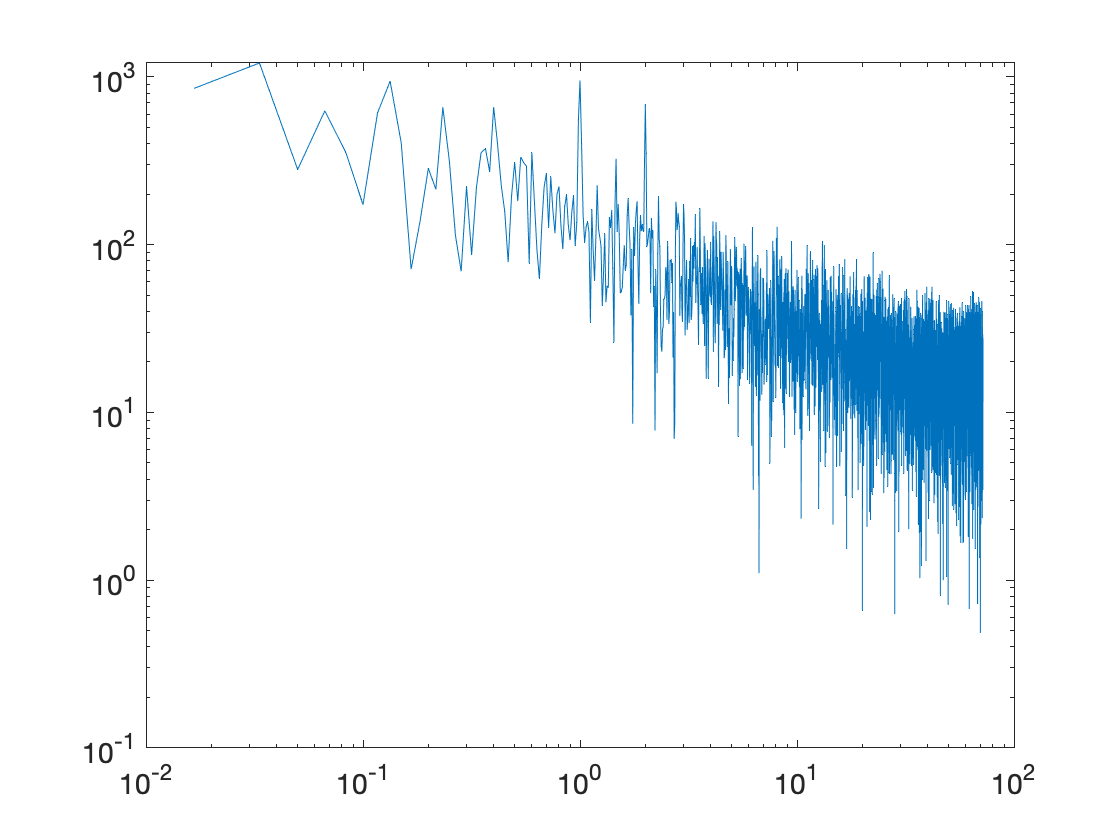

clf
loglog(x,y)